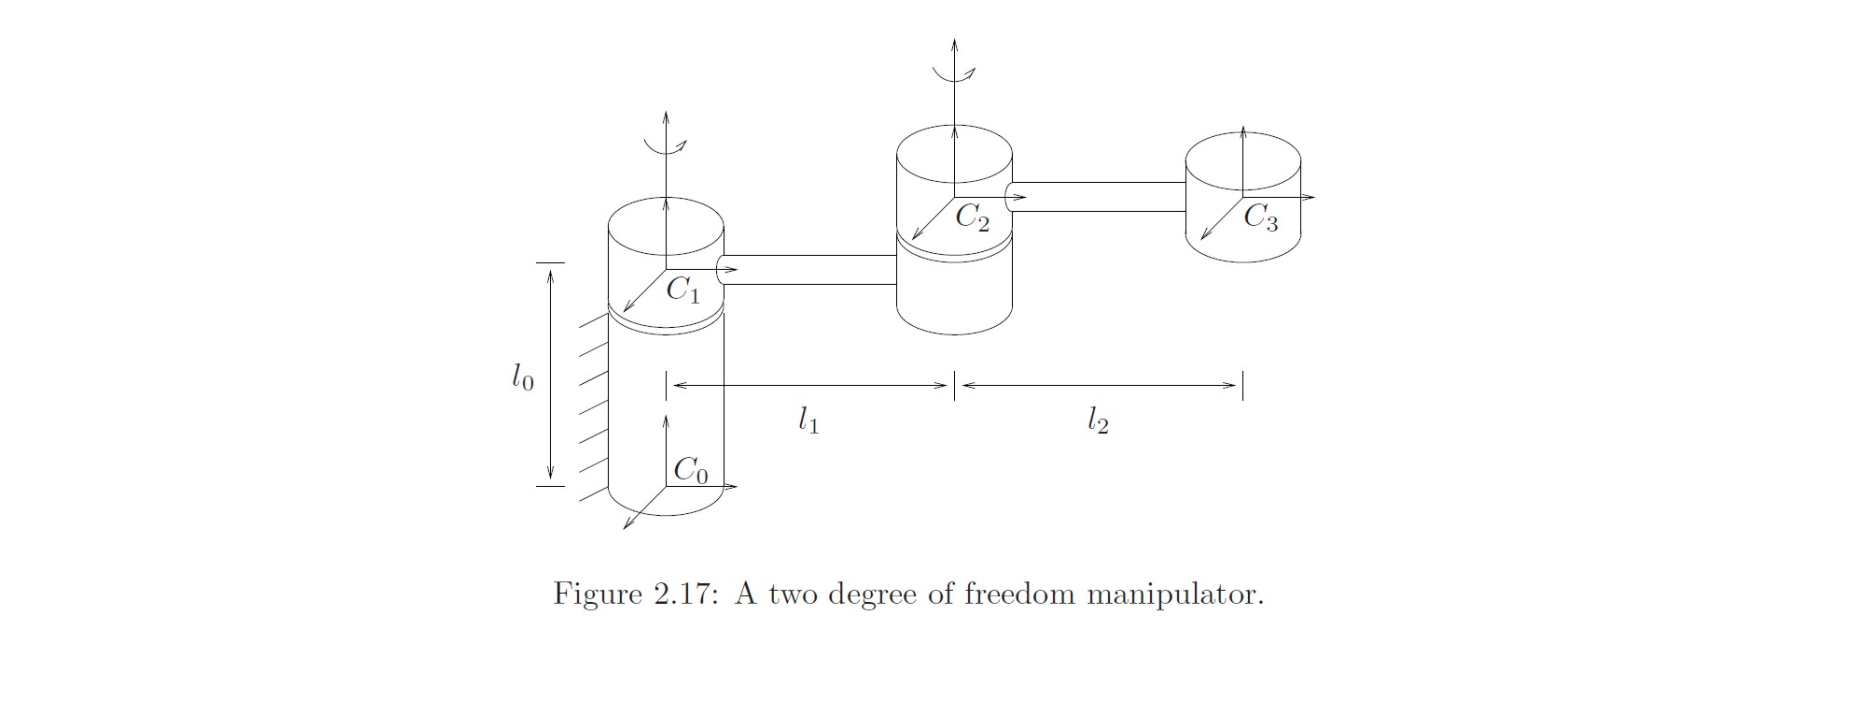


%要求：
%Use the homogeneous description of rigid motion on MATLAB and determine the coordinates of point C3
%in the inertial axis system, as well as the total angle through which the arm of C2 has rotated in the inertial
%axis system.

clc;clear

l0 = 0.8;
l1 = 0.45;
l2 = 0.45;

theta1 = deg2rad(60); theta2 = deg2rad(-120);

function Rz = Rz(theta)

Rz = [cos(theta) -sin(theta) 0;
    sin(theta) cos(theta) 0;
    0 0 1];
end

Rz1 = Rz(theta1)

Rz1 =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


Rz2 = Rz(theta2)

Rz2 =    -0.5000    0.8660         0
   -0.8660   -0.5000         0
         0         0    1.0000


p0 = [0;0;0;1];p1 = [0;0;l0]

p1 =          0
         0
    0.8000


p2 = [0;l1;0]

p2 =          0
    0.4500
         0


p3 = [0;l2;0]

p3 =          0
    0.4500
         0



g01 = [Rz1,p1
    0, 0, 0, 1] %从 0 到1 

g01 =     0.5000   -0.8660         0         0
    0.8660    0.5000         0         0
         0         0    1.0000    0.8000
         0         0         0    1.0000


g12 = [Rz2,p2;
    0,0,0,1]

g12 =    -0.5000    0.8660         0         0
   -0.8660   -0.5000         0    0.4500
         0         0    1.0000         0
         0         0         0    1.0000



g23 = [eye(3),p3;
    0,0,0,1]

g23 =     1.0000         0         0         0
         0    1.0000         0    0.4500
         0         0    1.0000         0
         0         0         0    1.0000



g03 = g01 * g12 * g23

g03 =     0.5000    0.8660         0         0
   -0.8660    0.5000         0    0.4500
         0         0    1.0000    0.8000
         0         0         0    1.0000


pfinal = g03 * p0

pfinal =          0
    0.4500
    0.8000
    1.0000


Rtot  =  g03(1:3,1:3)

Rtot =     0.5000    0.8660         0
   -0.8660    0.5000         0
         0         0    1.0000


axang = rotm2axang(Rtot)

axang =          0         0   -1.0000    1.0472


ax = axang(1:3)

ax =      0     0    -1


ang = rad2deg(axang(4))

ang = 60.0000